**ADMISSION CONTROL WITH PRIORITIZATION, QUEUEING, PRIORITIZATION AND BANDWIDTH THRESHOLD**

**Initializing System Variables**

% LOAD HOUR DATA FROM ATTACHED .mat FILES
load('testing_data.mat')

% The input is varied from Hour49 to Hour72
input = Hour49;                % Assign the hour traffic data to input
heading = "49";

input = input.';               % Transpose the input matrix

% MODIFY CAPACITY, THRESHOLD AND WINDOW
% The capacity is varied based on the traffic predictions
capacity = 2;                   % resource capacity of the system
threshld = 0.7*capacity;        % resource threshold is 70% of capacity
wndw = 10;                      % Servicing Window (duration of system)

% WORKING VARIABLES 
sz_req = size(input);
a = sz_req(1);
a2 = a + 1;
num_reqs = sz_req(2);                  % number of incoming requests to be managed
admitted = zeros(a2,num_reqs);          % starts off with empty set of admitted users
queue = zeros(a2,num_reqs);
serviced = [];
rej = [];
used = [];
arrivals = input;           % ... num_reqs requests are to be decided upon
arrivals(a2,:) = 0;         % REQUESTS ARRAY: row 1 = bandwidth requested,
                            % (trafficmatrix) row 2 = duration of flow, 
                            %                 row 3 = resource type with 1
                            %                         representing non-GBR
                            %                         and 2 rep'ping GBR.
                            %                 row 4 = utility index
                            %                 row 5 = revenue potential.
                        
bw_used = 0;                       % number of resources in use
num_admitted = 0;                  % number of admitted requests
num_rejected = 0;
num_queued = 0;
q_rejected = 0;                     % number queued but later rejected
available = capacity - bw_used;
used = [used, bw_used];
toplot = [];
count = 1;
t_start = cputime;
t_stop = t_start + wndw;        % We want admission control running for 30 seconds


**Admission Control**

% INVOKE ADMISSION CONTROL (FIFO, Admit/Reject/Queue/Prioritization)

while cputime<=t_stop
    for x=1:num_reqs                    % implementing Decision Matrix
        if arrivals(3,x)==3             % processing GBR requests first
            if arrivals(1,x)~=0 && (arrivals(1,x)+bw_used)<=capacity  % if available resources, admit call           
                admitted(:,x) = arrivals(:,x);      % Add admitted request and corresponding parameters
                num_admitted = num_admitted + 1;    % Count number of admitted requests
                admitted(a2,x) = cputime;           % Note the admission time of this request
                bw_used = sum(admitted(1,:));       % update used resources based on serviced requests
                toplot(count,:) = admitted(1,:);
                count = count + 1;             
                arrivals(:,x) = 0;                  % mark as treated
            else
                queue(:,x) = arrivals(:,x);
                queue(a2,x) = cputime;               % Note time flow was queued
                arrivals(:,x) = 0;                  % mark as treated
                num_queued = num_queued + 1;
            end
        end
    end                                           % go through all GBR requests before moving to nGBR
    
    [admitted2, serviced2] = req_servicing(admitted, t_start, a2);  % Call servicing function  
    if admitted ~= admitted2
        toplot(count,:) = admitted2(1,:);
        count = count + 1;
    end
    admitted = admitted2;               % updated admitted array after servicing
    bw_used = sum(admitted(1,:));       % update used resources based on serviced requests
    available = capacity - bw_used;      % update available resources 
    used = [used, bw_used];
    serviced = [serviced,serviced2];
   
    
    for x=1:num_reqs
        if arrivals(3,x) == 1                                                % processing non-GBR requests
            if arrivals(1,x)~=0 && (arrivals(1,x)+bw_used)<=threshld         % if requested bandwidth + bandwidth in use 
                                                                             % is less than or equal to threshold
                admitted(:,x) = arrivals(:,x);      % Add admitted request and corresponding parameters
                num_admitted = num_admitted + 1;
                admitted(a2,x) = cputime;           % Note the admission time of this request
                bw_used = sum(admitted(1,:));        % update used resources based on serviced requests
                available = capacity - bw_used;      % update available resources
                used = [used, bw_used];

                toplot(count,:) = admitted(1,:);
                count = count + 1;
                arrivals(:,x) = 0;                % mark as treated
            else if arrivals(1,x)~=0 && (arrivals(1,x)+bw_used)<=capacity
                queue(:,x) = arrivals(:,x);         % add to queue
                queue(a2,x) = cputime;           % Note the admission time of this request
                arrivals(:,x) = 0;                  % mark as treated, though not yet admitted 
                num_queued = num_queued + 1;
            else
                rej = [rej,arrivals(:,x)];
                arrivals(:,x) = 0;                % mark as treated, though not admitted
                num_rejected = num_rejected + 1;  % increment count of rejected requests
            end
            end
        end
        
        [admitted2, serviced2] = req_servicing(admitted, t_start, a2);  % Call servicing function
        if admitted ~= admitted2
            toplot(count,:) = admitted2(1,:);
            count = count + 1;
        end
            admitted = admitted2;               % updated admitted array after servicing
            bw_used = sum(admitted(1,:));       % update used resources based on serviced requests
            available = capacity - bw_used;      % update available resources          
            used = [used, bw_used];

            serviced = [serviced,serviced2];
    end
    
    [admitted2, serviced2] = req_servicing(admitted, t_start, a2);  % Call servicing function
    if admitted ~= admitted2
        toplot(count,:) = admitted2(1,:);
        count = count + 1;
    end
        admitted = admitted2;               % updated admitted array after servicing
        bw_used = sum(admitted(1,:));       % update used resources based on serviced requests
        available = capacity - bw_used;      % update available resources          
        used = [used, bw_used];

        serviced = [serviced,serviced2];

        

**Queue Management**

        
    for x=1:num_reqs
        if (bw_used+queue(1,x))<=capacity && queue(1,x)~=0
            if queue(1,x)<=available   % if available resources, admit call
                admitted(:,x) = queue(:,x);         % Add admitted request and corresponding parameters
                num_admitted = num_admitted + 1;
                admitted(a2,x) = cputime;           % Note the admission time of this request
                bw_used = sum(admitted(1,:));       % update used resources based on serviced requests
                available = capacity - bw_used;     % update available resources
                used = [used, bw_used];

                toplot(count,:) = admitted(1,:);
                count = count + 1;
                queue(:,x) = 0; 
            else
                rej = [rej,queue(:,x)];
                queue(:,x) = 0;                     % mark as treated, though not admitted
                num_rejected = num_rejected + 1;    % increment count of rejected requests
                q_rejected = q_rejected + 1;
            end
        end
        [admitted2, serviced2] = req_servicing(admitted, t_start, a2);  % Call servicing function
        if admitted ~= admitted2
            toplot(count,:) = admitted2(1,:);
            count = count + 1;
        end
        admitted = admitted2;               % updated admitted array after servicing
        bw_used = sum(admitted(1,:));       % update used resources based on serviced requests
        available = capacity - bw_used;      % update available resources          
        used = [used, bw_used];

        serviced = [serviced,serviced2];
    end
end
    
elapsed = cputime - t_start;    

**Plotting the Flow Decisions and Allocations (Animation)**

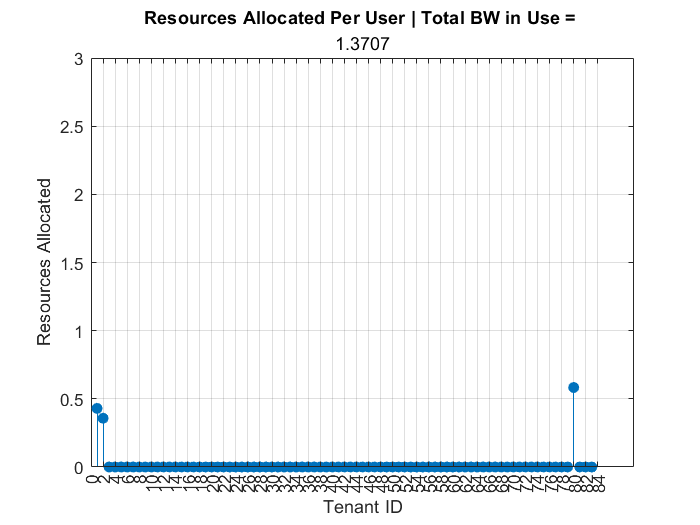


p = size(toplot);
q = p(1);
r = 1:num_reqs;
system_state = zeros(1,q);
figure()
    for i = 1:q
        y = toplot(i,:);
        system_state(i) = sum(y);
        stem(r,y,"filled","LineStyle","-","Marker","o")
        set(gca,'xtick', 0:2:num_reqs+1)
        ylim([0, capacity+1])
        title('Resources Allocated Per User | Total BW in Use = ', sum(y))
        xlabel('Tenant ID')
        ylabel('Resources Allocated')
        grid("on")
        drawnow;
        %pause(1)
    end

**Calculating the Performance Metrics**

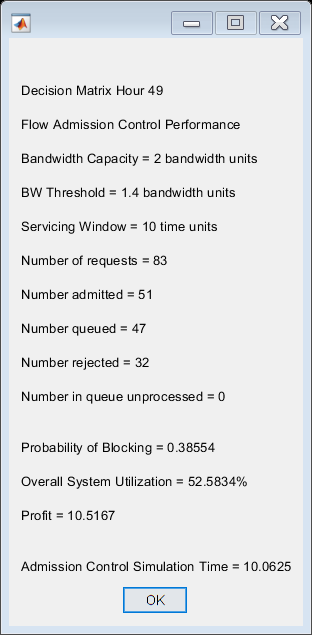

profit = sum(serviced(5,:))+sum(admitted(5,:));
total_rev_potential = sum(input(5,:));
q_unprocessed = nnz(queue(1,:));
syst_u = sum(serviced(1,:).*serviced(2,:))/(capacity*wndw) + sum(admitted(1,:).*(t_stop-admitted(6,:)))/(capacity*wndw);
PoB = 1 - (num_admitted/num_reqs);                 % Calculating probability of blocking
PoB2 = num_rejected/num_reqs;                      % PoB is more accurate than PoB2

msg = msgbox("Decision Matrix " + "Hour " + heading + newline + newline + ...
    "Flow Admission Control Performance"+ newline + newline + ...
    "Bandwidth Capacity = " + capacity + " bandwidth units" + newline + newline +...
    "BW Threshold = " + threshld + " bandwidth units" + newline + newline +......
    "Servicing Window = " + wndw + " time units" + newline + newline +...
    "Number of requests = " + num_reqs + newline + newline + ...
    "Number admitted = " + num_admitted + newline + newline +...
    "Number queued = " + num_queued + newline + newline +...
    "Number rejected = "+ num_rejected + newline + newline + ...
    "Number in queue unprocessed = "+ q_unprocessed + newline + newline + newline +...
    "Probability of Blocking = " + PoB + newline + newline + ...
    "Overall System Utilization = "+ syst_u*100 + "%" + newline + newline + ...
    "Profit = "+ profit + newline + newline + newline +...
    "Admission Control Simulation Time = " + elapsed);

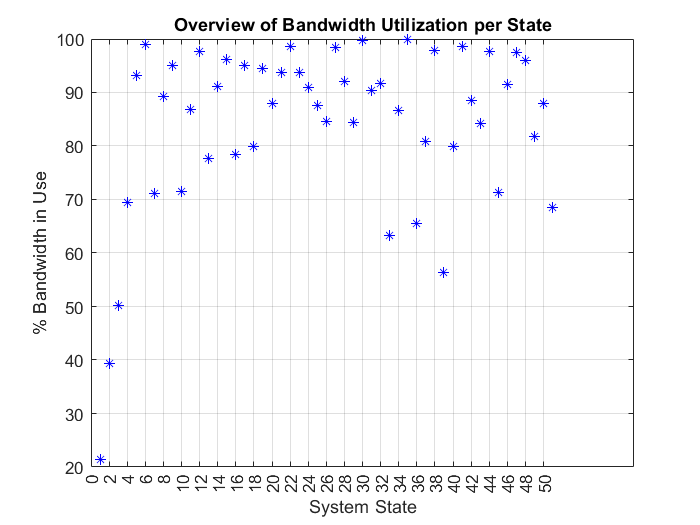

    
figure
bandwidth_u_state = system_state./capacity;     % bandwidth utilization per state
plot(bandwidth_u_state*100,"LineStyle","none","Color","blue","Marker","*")
title('Overview of Bandwidth Utilization per State')
ylabel('% Bandwidth in Use')
xlabel('System State')
set(gca,'xtick', 0:2:numel(bandwidth_u_state))
grid on

**Request Servicing Function**

function [ongoing, served] = req_servicing(x, t, a2)
    n = numel(x(1, :));
    p = x(2, :);        % Requested duration of flow
    t = x(a2, :);        % Flow admission time (flow start time)
    served = [];
    ongoing = x;
    t_now = cputime;
    for m = 1:n
        if t_now-t(m) >= p(m) && x(1,m)~=0      % if running time >= requested duration
            served = [served, x(:,m)];
            ongoing(:,m) = 0;
        end       
    end
end




